# Controladores

## Integración de Euler en un motor CC

Se tiene un modelo de un motor de corriente continua con un torque de carga en el rotor. Las ecuaciones que lo relacionan dinamicamente son:


$$i_f' = \frac{R_F}{L_{FF}} i_f + \frac{1}{L_{FF}} V_f $$



$$i_a' = -\frac{R_A}{L_{AA}} i_a-\frac{L_{AF}}{L_{AA}} i_f \omega_r + \frac{1}{L_{AA}} V_A$$



$$\omega_r' = -\frac{B_m}{J} \omega_r+\frac{L_{AF}}{J} i_f i_a-\frac{1}{J} T_L$$


Si la corriente de magnetizacion es constante podemos simplificar la ecuación de la siguiente forma:


$$K_i = -\frac{L_{AF}}{J} i_f$$



$$T_m = K_i i_a$$



$$ i_a' = -\frac{R_A}{L_{AA}} i_a-\frac{K_m}{L_{AA}} \omega_r + \frac{1}{L_{AA}} V_A$$



$$\omega_r' = -\frac{B_m}{J} \omega_r+\frac{K_i}{J} i_a-\frac{1}{J} T_L$$


Determinamos la función de transferencia para $T_L = 0$

syms Va Ra Laa ia Km w Jm Ki Bm s real
eq2=Jm*s*w==Ki*ia-Bm*w;
eq1=Va==Ra*ia+Laa*s*ia+Km*w;
S1=solve(eq1,eq2,w,Va);
G=S1.w/S1.Va

$$G = \frac{\mathrm{Ki}\,\mathrm{ia}}{\mathrm{Bm}\,\mathrm{Ra}\,\mathrm{ia}+\mathrm{Ki}\,\mathrm{Km}\,\mathrm{ia}+\mathrm{Jm}\,\mathrm{Laa}\,\mathrm{ia}\,s^{2}+\mathrm{Bm}\,\mathrm{Laa}\,\mathrm{ia}\,s+\mathrm{Jm}\,\mathrm{Ra}\,\mathrm{ia}\,s}$$

Asignamos los valores correspondientes al motor

clear all;
Laa=366e-6;
J=5e-9;
Ra=55.6;
B=0;
Ki=6.49e-3;
Km=6.53e-3;

num=[Ki];
den=[Laa*J Ra*J+Laa*B Ra*B+Ki*Km];
sys=tf(num,den)

sys =
 
                 0.00649
  -------------------------------------
  1.83e-12 s^2 + 2.78e-07 s + 4.238e-05
 
Continuous-time transfer function.



p = pole(sys)

p = 	1.0e+05 *

   -1.5176
   -0.0015


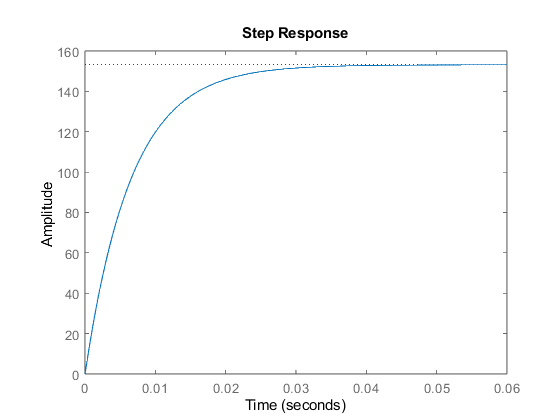

step(sys)

`Si observamos la función de transferencia del motor, podemos observar que los polos son `$p_1 = -1.51e05  $, $p_2 = -1.52e02 $`. El tiempo al que corresponde el 95% de la dinámica mas rápida es `

tR = log(0.95)/p(1)

tR = 3.3799e-07

El tiempo de integración debe ser menor que este mismo, por ejemplo tomamos tres veces menor, es decir 1e-07. 

Para calcular el tiempo de simulación tomamos la constante mas lenta y calculamos el tiempo para 0.05% de la dinámica más lenta.

tL = log(0.05)/p(2)

tL = 0.0196

Tomamos el triple de este valor, es decir 0.06.

Vamos a simular el desarollo de las variables de estado con respuesta al escalón unitario usando integración de Euler. El motor se encuentra controlador por un PID de la forma


$$u(k)=u(k-1)+Ae(k)+Be(k-1)+Ce(k-2)$$


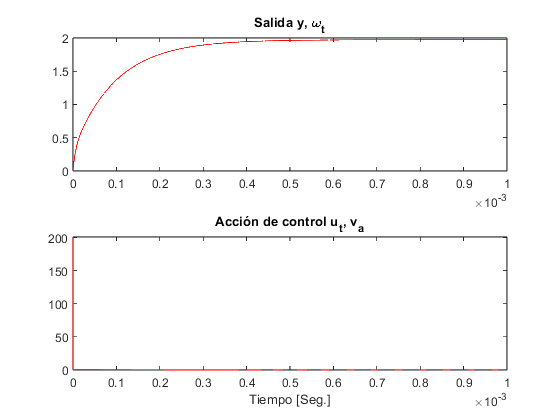

X=-[0; 0];ii=0;t_etapa=1e-7;wRef=2;tF=.001;
%Constantes del PID
Kp=.500;Ki=0.001;Kd=0.00001;color_='r';
% Kp=1;Ki=0;Kd=0.0001;color_='k';
% Kp=10;Ki=0;Kd=0;color_='b';
Ts=t_etapa;
A1=((2*Kp*Ts)+(Ki*(Ts^2))+(2*Kd))/(2*Ts); %Coeficientes PID discreto
B1=(-2*Kp*Ts+Ki*(Ts^2)-4*Kd)/(2*Ts);
C1=Kd/Ts;
e=zeros(tF/t_etapa,1);u=0;
for t=0:t_etapa:tF
  ii=ii+1;
  k=ii+2; 
  X=modmotor(t_etapa, X, u); %modmotor.m
  e(k)=wRef-X(1); %ERROR
  u=u+A1*e(k)+B1*e(k-1)+C1*e(k-2); %PID
  x1(ii)=X(1);  %Omega
  x2(ii)=X(2);  %wp
  acc(ii)=u;    %Accion de control
end
t=0:t_etapa:tF;
figure
subplot(2,1,1)
plot(t,x1,color_);title('Salida y, \omega_t');
subplot(2,1,2)
plot(t,acc,color_);title('Acción de control u_t, v_a');
xlabel('Tiempo [Seg.]');

## Diseño de un controlador lineal en procesos lineales

Sea la funcion de transferencia de lazo abierto del sistema


$$G(s) = \frac{2s-1}{s^^2+3s+6$$


Compensar en adelanto y luego mediante un controlador PI establecer error nulo en regulación.

clear all;
G = tf([2 -1], [1 3 6])

G =
 
     2 s - 1
  -------------
  s^2 + 3 s + 6
 
Continuous-time transfer function.



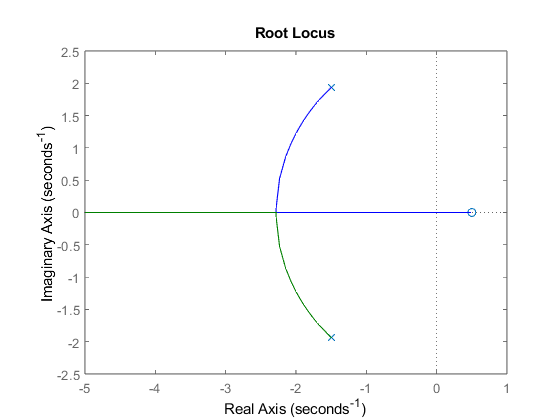

figure
rlocus(G)

T1 = 1/3;
T2 = 1/4;
alfa = T2/T1 % verificamos que de entre 0 y 1 (adelanto)

alfa = 0.7500

kc = 1

kc = 1

C = tf(kc*[1 1/T1], [1 1/(T2)])

C =
 
  s + 3
  -----
  s + 4
 
Continuous-time transfer function.



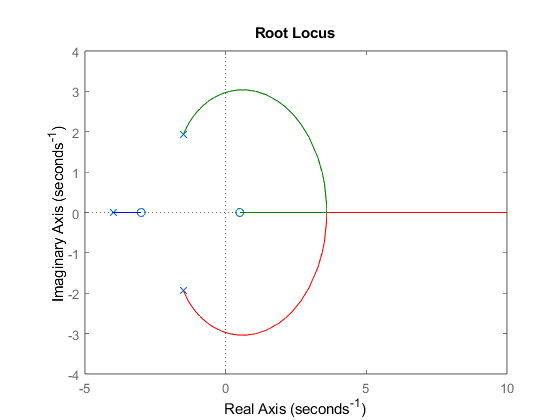

rlocus(-C*G)

Tomamos la ganancia $k = 1.1$

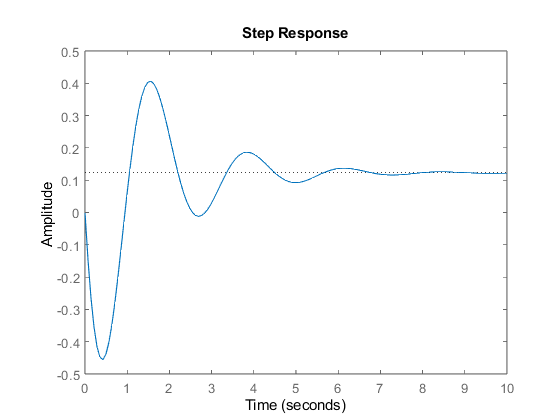

FLC = feedback(-1.12*C*G,1);
step(FLC)

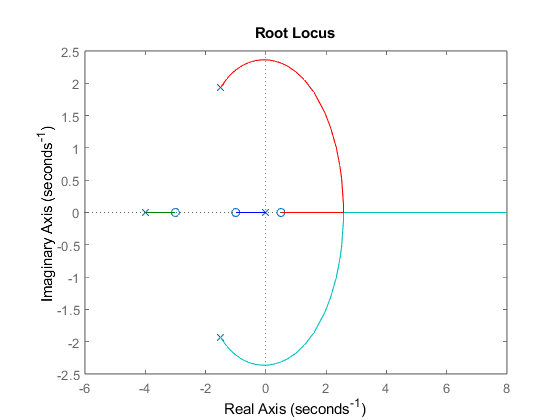

Kp=1;Ki=1;
C2 = tf(Kp*[1 Ki/Kp],[1 0]);
rlocus(-1*C*C2*G)

## Caso 1

Sea la función de transferencia de lazo abierto 
